# Weighted Sampled Average Estimator: Unbiasedness and Mean Square Convergence

## Motivating Example

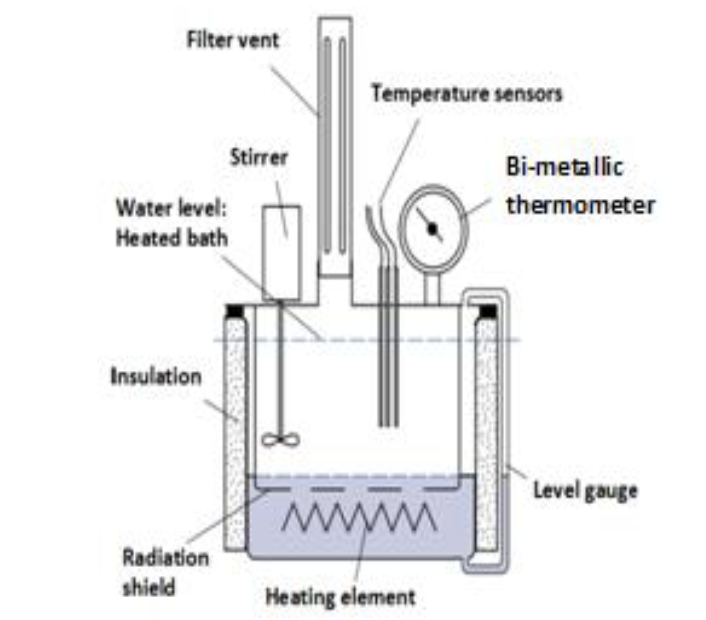

We want to measure the water temperature in an insulated stainless steel stirrer, as in Fig. 1. The water is heated with an immersion heater. We have both a thermocouple and an RTD sensor to perform the measurements. The experiment involves heating a predetermined amount of water and measuring temperature using both devices. The stirrer has good insulating capabilities, so it is assumed that the water maintains a constant temperature after the heating phase. The thermocouple and the RTD sensor provide measurements that are random variables, all with the same expected value but with different variances (and constant for each device). How can the temperature best be estimated (i.e., with an unbiased estimator and minimum variance)?

## The Weighted Sampled Average Estimator: the Features	

Given $N$ random variables $\, d(1)\,,\; d(2)\,,\; \ldots\,,\; d(N) \,$such that


$$\text{E} \left[ d(i) \right] = \vartheta^{\circ}\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  d(i) - \vartheta^{\circ} \right] \, \left[ d(j) - \vartheta^{\circ} \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **weighted** **sampled-average estimator**				


$$\hat{\vartheta}_{N} = \sum_{i=1}^{N}\, \alpha(i) \, d(i) \qquad \sum_{i=1}^{N} \, \alpha(i) = 1 $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\vartheta}_{N}\right] = \vartheta^{\circ}$$
			

Moreover, the variance of the estimate is

$\alpha(i) = \frac{1}{\text{var} \left[ d(i) \right]}  \displaystyle \cdot  \frac{1}{\displaystyle \sum_{i=1}^{N} \displaystyle \frac{1}{\text{var} \left[ d(i) \right]}} \quad \Longrightarrow \quad \text{var} \left( \hat{\vartheta}_{N} \right) = \displaystyle  \frac{1}{\sum_{i=1}^{N} \frac{1}{\text{var} \left[ d(i) \right]}}$         (1)

If $$\text{var} \left[ d(i) \right] \le \bar{\sigma}\, , \; i =1\,,\; 2\,,\; \ldots \,,\; N$  	 $then 


$$\lim_{N \to \infty} \text{var} \left( \hat{\vartheta}_{N} \right) \le \lim_{N \to \infty} \frac{\bar{\sigma}}{N}=0$$


Thus, the **estimator converges in quadratic mean**. This implies also that the $\hat \vartheta_N$ is a **consistent estimator** of the mean value.

## Hands-On: Estimation of the Mean Value from Two Data Sets

In this example we study the sample mean that is calculated from two data sets $D^T=[D_1^T \text{ } D_2^T]$. Both data sets have the same mean value $\vartheta^{\circ}$ but a different variance $\sigma_{v_1}^2,\sigma_{v_2}^2$ respectively. Assume $N_1$ data with variance $\sigma_{v_1}^2$ and $N_2$ data with variance $\sigma_{v_2}^2$, with $N_1+N_2=N$.

We will calculate the variance twice:

-  The first time for a weighted estimate, according to Eq. (1);

- The second time using a classical sampled-average estimator, i.e. with $\alpha(i) =1\;\forall i$.

clear 
close all
clc

Ntot = 100;    % total number of samples
theta0 = 12.5; % the "true" mean value 

N1 =12;  % set N1
N2 = Ntot-N1; % set N2


Now let's assign the variances

sigma2_v1 = 100; % set the variance v1
sigma2_v2 = 1; % fix variance v2 to 1

Generate the data:

d1 = theta0 + sqrt(sigma2_v1)*randn(N1,1); % D1 dataset
d2 = theta0 + sqrt(sigma2_v2)*randn(N2,1); % D1 dataset

### Weighted Sampled-Average Estimate

According to Eq. (1), when $d(i) \in D_1$


$$\forall j: d(j) \in D_1\,,\quad \text{var}\big(d(j)\big) = \sigma^2_{v_1} \quad \Longrightarrow \quad \alpha(j) = \frac{1}{\text{var} \left[ d(j) \right]}  \displaystyle \cdot  \frac{1}{\displaystyle \sum_{i=1}^{N} \displaystyle \frac{1}{\text{var} \left[ d(i) \right]}} = \frac{1}{\sigma^2_{v_1}} \cdot  \frac{1}{\displaystyle \frac{N_1}{\sigma^2_{v_1}}+\frac{N_2}{\sigma^2_{v_2}}$$


Thus


$$\hat \vartheta_{WN}=\frac{\sum_{p=1}^{N_1}\frac{d_{1,p}}{\sigma_{v_1}^2}+\sum_{q=1}^{N_2}\frac{d_{2,q}}{\sigma_{v_2}^2}}{\frac{N_1}{\sigma_{v_1}^2}+\frac{N_2}{\sigma_{v_2}^2}}.$$
        
$$\sigma^2_{\hat{\vartheta}_{W N}} =
\Big(\frac{N_1}{\sigma^2_{v_1}}+\frac{N_2}{\sigma^2_{v_2}}  \Big)^{-1}
$$


whereas


$$\hat{\vartheta}_{N}= \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} d(i) $$
        
$$\text{var} \left( \hat{\vartheta}_{N} \right) = \displaystyle \frac{1}{N^2} \sum_{i=1}^{N}\,\text{var}\big(d(i)\big) = 
\frac{N_1\sigma_{v_1}^2+N_2\sigma_{v_2}^2}{N^2}$$


Try

- $N_1 = N_2 = N/2$. Compare the estimates and the variances using both the estimators;

- $N_1 \ll N_2$ . Compare the estimates and the variances using both the estimators;

- $N_1 \gg N_2$ . Compare the estimates and the variances using both the estimators;

alpha1 = (1/sigma2_v1)*ones(N1,1); % the weights for the D1 dataset
alpha2 = (1/sigma2_v2)*ones(N2,1); % the weights for the D2 dataset

hat_theta_W = (sum(alpha1 .* d1) + sum(alpha2 .* d2)) / ((N1/sigma2_v1) + (N2/sigma2_v2))

hat_theta_W = 12.3952

var_hat_theta_W = 1/((N1/sigma2_v1) + (N2/sigma2_v2))

var_hat_theta_W = 0.0113


hat_theta_N = mean([d1; d2])

hat_theta_N = 12.7111

var_hat_theta_N = (N1*sigma2_v1+N2*sigma2_v2)/(Ntot^2)

var_hat_theta_N = 0.1288

### Discussion

The result allow us to state that the weighted estimate is dominated by the best measurements, while the standard sampled-average estimate is dominated by the worst measurements.

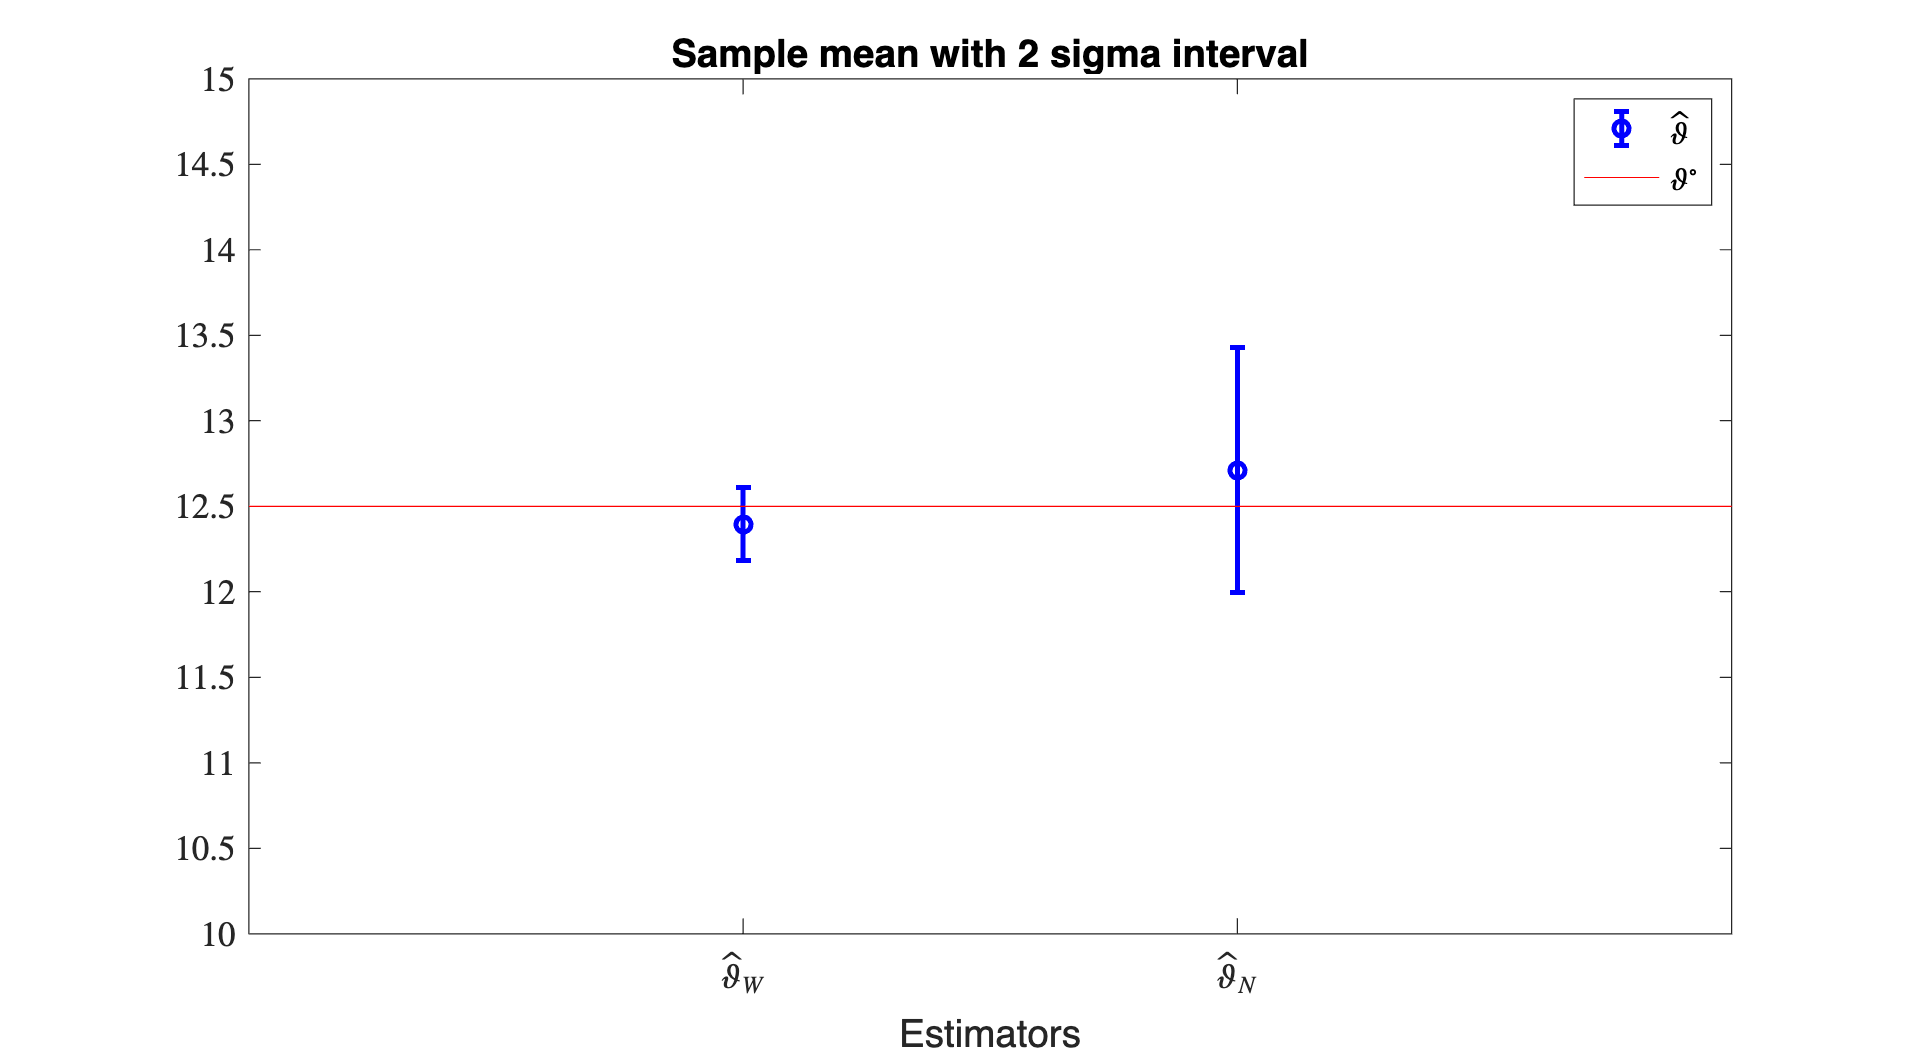

a =2;    % number of standard deviations

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

hat_theta = [hat_theta_W ; hat_theta_N];     % the estimated mean value
hat_sigma = [sqrt(var_hat_theta_W); sqrt(var_hat_theta_N)]; 
% the std. dev. of the estimated mean value

R = numel(hat_theta);

errorbar(hat_theta,a*hat_sigma,'ob','linewidth',2)
hold on
plot((0:R+1),theta0*ones(1,R+2),'r')
hold off
axis([0 R+1 0.8*theta0 1.2*theta0])
legend('$\hat\vartheta$','$\vartheta^{\circ}$','Interpreter','latex')
xlabel('Estimators')
ax = gca;
ax.XTick = [1 2];
ax.XTickLabel = {'$\hat{\vartheta}_{W}$','$\hat{\vartheta}_{N}$'};
ax.TickLabelInterpreter = "latex";
title(['Sample mean with ',num2str(a),' sigma interval'])
set(gca, 'Fontsize', 14);